% Expand Fourier series of periodic functions f(x) with period T, 
% given on the indicated intervals:
% f(x)=-2*x on [-pi;0]
%       3*x  on [0;pi]
% T=2*pi;

clear
pi1=pi;
syms x real;
syms pi;
f(x)=piecewise(-pi<=x<=0,-2*x,0<=x<=pi,3*x)

$$f(x) = \left\{ \begin{array}{cl} -2\,x & \text{ if }x\in \left[-\pi ,0\right]\\ 3\,x & \text{ if }x\in \left[0,\pi \right] \end{array}\right.$$


syms m integer;
[a0,a(m),b(m),abf(m)]=fourierseries(f)

$$a0 = \frac{5\,\pi }{2}$$

$$a(m) = \frac{5\,{\left(-1\right)}^{m}-5}{m^{2}\,\pi }$$

$$b(m) = -\frac{{\left(-1\right)}^{m}}{m}$$

$$abf(m) = \frac{\cos\left(m\,x\right)\,\left(5\,{\left(-1\right)}^{m}-5\right)}{m^{2}\,\pi }-\frac{{\left(-1\right)}^{m}\,\sin\left(m\,x\right)}{m}$$

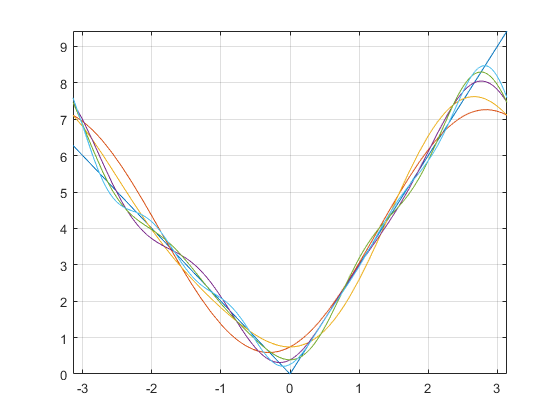


fplot(f(x),[-pi1 pi1]);
grid on
hold on

f1=a0/2;
for m=1:5
    m1(m)=m;
    a1(m)=a(m);
    b1(m)=b(m);
    abf1(m)=abf(m);
    f1=f1+abf(m);
    fplot(f1,[-pi1 pi1])
    grid on
end
hold off


a0/2

$$ans = \frac{5\,\pi }{4}$$

% (5*pi)/4
ft=[m1;a1;b1;abf1];
ft'

$$ans = \left(\begin{array}{cccc} 1 & -\frac{10}{\pi } & 1 & \sin\left(x\right)-\frac{10\,\cos\left(x\right)}{\pi }\\ 2 & 0 & -\frac{1}{2} & -\frac{\sin\left(2\,x\right)}{2}\\ 3 & -\frac{10}{9\,\pi } & \frac{1}{3} & \frac{\sin\left(3\,x\right)}{3}-\frac{10\,\cos\left(3\,x\right)}{9\,\pi }\\ 4 & 0 & -\frac{1}{4} & -\frac{\sin\left(4\,x\right)}{4}\\ 5 & -\frac{2}{5\,\pi } & \frac{1}{5} & \frac{\sin\left(5\,x\right)}{5}-\frac{2\,\cos\left(5\,x\right)}{5\,\pi } \end{array}\right)$$

% [ 1,     -10/pi,    1,           sin(x) - (10*cos(x))/pi]
% [ 2,          0, -1/2,                       -sin(2*x)/2]
% [ 3, -10/(9*pi),  1/3, sin(3*x)/3 - (10*cos(3*x))/(9*pi)]
% [ 4,          0, -1/4,                       -sin(4*x)/4]
% [ 5,  -2/(5*pi),  1/5,  sin(5*x)/5 - (2*cos(5*x))/(5*pi)]
